% ------------------------------------------------------------------------
% MATLAB SCRIPT: Sequential FT-IR Spectral Preprocessing & Visualization Workflow
% ------------------------------------------------------------------------
% This script applies a 3-step preprocessing sequence:
% 1. Savitzky-Golay Smoothing
% 2. Standard Normal Variate (SNV) Normalization (on smoothed spectra)
% 3. L2-Norm Vector Normalization (on SNV-smoothed spectra)
%
% It also includes:
% - Visualization of a single example spectrum through all stages.
% - A detailed comparative visualization of all spectra from two specified
%   positions across all stages, saved as .fig and .tif.
%
% Prerequisites in your MATLAB workspace:
%   1. 'data_all_positions': A MATLAB table with 'RawSpectrum', 'Proben_ID_str', 'Position'.
%   2. 'wavenumbers_roi': The wavenumber vector.
% ------------------------------------------------------------------------

%% --- Section 0: Configuration and Prerequisites Check ---
fprintf('Starting sequential preprocessing and visualization workflow...\n');

Starting sequential preprocessing and visualization workflow...



% --- User-configurable Parameters ---
% Savitzky-Golay Smoothing Parameters (TUNE THESE)
sg_poly_order = 2; 
sg_frame_len = 11;  

% Example spectrum for single spectrum visualization
vis_example_pos_row_idx = 1;
vis_example_spec_in_block_idx = 1;

% Positions for detailed comparative 4x2 plot
vis_detail_pos_idx_1 = 149; % e.g., your "bad" example
vis_detail_pos_idx_2 = 158; % e.g., your "good" example

% --- Prerequisite Checks ---
if ~exist('data_all_positions', 'var') || ~istable(data_all_positions)
    error('Table "data_all_positions" not found or is not a table.');
end
required_cols_input = {'RawSpectrum', 'Proben_ID_str', 'Position'};
if any(~ismember(required_cols_input, data_all_positions.Properties.VariableNames))
    error('Input table "data_all_positions" is missing required columns: %s', strjoin(required_cols_input, ', '));
end
if ~exist('wavenumbers_roi', 'var') || ~isvector(wavenumbers_roi)
    error('Wavenumber vector "wavenumbers_roi" not found or is not a vector.');
end
if mod(sg_frame_len, 2) == 0 || sg_frame_len <= sg_poly_order
    error('Savitzky-Golay frame length must be odd and greater than polynomial order.');
end

if iscolumn(wavenumbers_roi), wavenumbers_roi = wavenumbers_roi'; end
num_wavenumber_points = length(wavenumbers_roi);
if isempty(data_all_positions.RawSpectrum{1}) || size(data_all_positions.RawSpectrum{1},2) ~= num_wavenumber_points
    error('Wavenumber length mismatch with RawSpectrum{1}.');
end

%% --- Step 1: Savitzky-Golay Smoothing (on RawSpectrum) ---
fprintf('\nWorkflow Step 1: Applying Savitzky-Golay Smoothing...\n');


Workflow Step 1: Applying Savitzky-Golay Smoothing...


numBlocks = height(data_all_positions);
Smoothed_Spectra_cell_S1 = cell(numBlocks, 1);
for i = 1:numBlocks
    currentBlockOfRawSpectra = data_all_positions.RawSpectrum{i};
    if isempty(currentBlockOfRawSpectra) || ~ismatrix(currentBlockOfRawSpectra), Smoothed_Spectra_cell_S1{i} = currentBlockOfRawSpectra; continue; end
    smoothedBlock_S1 = zeros(size(currentBlockOfRawSpectra));
    for j = 1:size(currentBlockOfRawSpectra, 1)
        spectrum_to_smooth = currentBlockOfRawSpectra(j,:);
        if any(isnan(spectrum_to_smooth)) || length(spectrum_to_smooth) < sg_frame_len, smoothedBlock_S1(j,:) = spectrum_to_smooth; continue; end
        try, smoothedBlock_S1(j,:) = sgolayfilt(spectrum_to_smooth, sg_poly_order, sg_frame_len);
        catch ME_sgolay, warning('Row %d, Spec %d (Smoothing): Error: %s. Keeping original.', i, j, ME_sgolay.message); smoothedBlock_S1(j,:) = spectrum_to_smooth; end
    end
    Smoothed_Spectra_cell_S1{i} = smoothedBlock_S1;
end
data_all_positions.SmoothedSpectrum = Smoothed_Spectra_cell_S1;
disp('Savitzky-Golay smoothing complete. Column "SmoothedSpectrum" added/updated.');

Savitzky-Golay smoothing complete. Column "SmoothedSpectrum" added/updated.



%% --- Step 2: SNV Normalization (on SmoothedSpectrum) ---
fprintf('\nWorkflow Step 2: Applying SNV Normalization to SmoothedSpectrum...\n');


Workflow Step 2: Applying SNV Normalization to SmoothedSpectrum...


SNV_on_Smoothed_Spectra_cell_S2 = cell(numBlocks, 1);
for i = 1:numBlocks
    currentBlockOfSmoothedSpectra = data_all_positions.SmoothedSpectrum{i};
    if isempty(currentBlockOfSmoothedSpectra) || ~ismatrix(currentBlockOfSmoothedSpectra), SNV_on_Smoothed_Spectra_cell_S2{i} = currentBlockOfSmoothedSpectra; continue; end
    snv_on_smoothed_block_S2 = zeros(size(currentBlockOfSmoothedSpectra));
    for j = 1:size(currentBlockOfSmoothedSpectra, 1)
        spectrum_to_snv = currentBlockOfSmoothedSpectra(j,:);
        if any(isnan(spectrum_to_snv)) || all(spectrum_to_snv == 0), snv_on_smoothed_block_S2(j,:) = spectrum_to_snv; continue; end
        mean_val = mean(spectrum_to_snv, 'omitnan'); std_val = std(spectrum_to_snv, 0, 'omitnan');
        if std_val < eps, snv_on_smoothed_block_S2(j,:) = spectrum_to_snv; else, snv_on_smoothed_block_S2(j,:) = (spectrum_to_snv - mean_val) / std_val; end
    end
    SNV_on_Smoothed_Spectra_cell_S2{i} = snv_on_smoothed_block_S2;
end
data_all_positions.SNV_on_Smoothed_Spectrum = SNV_on_Smoothed_Spectra_cell_S2;
disp('SNV normalization on smoothed spectra complete. Column "SNV_on_Smoothed_Spectrum" added/updated.');

SNV normalization on smoothed spectra complete. Column "SNV_on_Smoothed_Spectrum" added/updated.



%% --- Step 3: L2-Norm Vector Normalization (on SNV_on_Smoothed_Spectrum) ---
fprintf('\nWorkflow Step 3: Applying L2-Norm Vector Normalization to SNV_on_Smoothed_Spectrum...\n');


Workflow Step 3: Applying L2-Norm Vector Normalization to SNV_on_Smoothed_Spectrum...


Final_Processed_Spectra_cell_S3 = cell(numBlocks, 1);
for i = 1:numBlocks
    currentBlockOf_SNV_on_Smoothed = data_all_positions.SNV_on_Smoothed_Spectrum{i};
    if isempty(currentBlockOf_SNV_on_Smoothed) || ~ismatrix(currentBlockOf_SNV_on_Smoothed), Final_Processed_Spectra_cell_S3{i} = currentBlockOf_SNV_on_Smoothed; continue; end
    final_processed_block_S3 = zeros(size(currentBlockOf_SNV_on_Smoothed));
    for j = 1:size(currentBlockOf_SNV_on_Smoothed, 1)
        spectrum_to_L2norm = currentBlockOf_SNV_on_Smoothed(j,:);
        if any(isnan(spectrum_to_L2norm)) || all(spectrum_to_L2norm == 0), final_processed_block_S3(j,:) = spectrum_to_L2norm; continue; end
        euclidean_norm = norm(spectrum_to_L2norm, 2);
        if abs(euclidean_norm) < eps, final_processed_block_S3(j,:) = spectrum_to_L2norm; else, final_processed_block_S3(j,:) = spectrum_to_L2norm / euclidean_norm; end
    end
    Final_Processed_Spectra_cell_S3{i} = final_processed_block_S3;
end
data_all_positions.FinalProcessedSpectrum = Final_Processed_Spectra_cell_S3;
disp('L2-Norm Vector normalization complete. Column "FinalProcessedSpectrum" added/updated.');

L2-Norm Vector normalization complete. Column "FinalProcessedSpectrum" added/updated.



%% --- Step 4a: Visualization of an Example Spectrum Through All Stages ---
fprintf('\nWorkflow Step 4a: Generating visualization of sequential preprocessing for example spectrum...\n');


Workflow Step 4a: Generating visualization of sequential preprocessing for example spectrum...


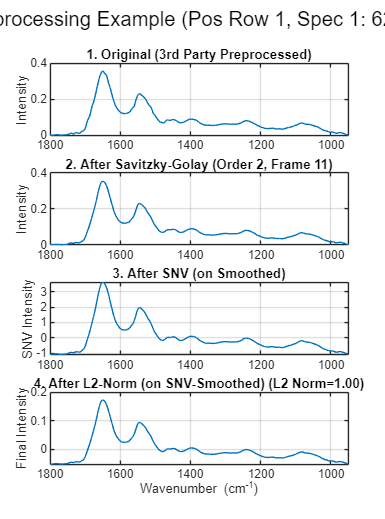

Example spectrum visualization created.


if vis_example_pos_row_idx <= height(data_all_positions) && vis_example_pos_row_idx >= 1 && ...
   ~isempty(data_all_positions.RawSpectrum{vis_example_pos_row_idx}) && ...
   vis_example_spec_in_block_idx <= size(data_all_positions.RawSpectrum{vis_example_pos_row_idx},1) && ...
   vis_example_spec_in_block_idx >= 1
    
    spec_raw_vis = data_all_positions.RawSpectrum{vis_example_pos_row_idx}(vis_example_spec_in_block_idx, :);
    spec_smooth_vis = data_all_positions.SmoothedSpectrum{vis_example_pos_row_idx}(vis_example_spec_in_block_idx, :);
    spec_snv_on_smooth_vis = data_all_positions.SNV_on_Smoothed_Spectrum{vis_example_pos_row_idx}(vis_example_spec_in_block_idx, :);
    spec_final_vis = data_all_positions.FinalProcessedSpectrum{vis_example_pos_row_idx}(vis_example_spec_in_block_idx, :);

    figure; % New figure for this specific visualization
    sgtitle(sprintf('Sequential Preprocessing Example (Pos Row %d, Spec %d: %s, %s)', ...
        vis_example_pos_row_idx, vis_example_spec_in_block_idx, ...
        data_all_positions.Proben_ID_str{vis_example_pos_row_idx}, ...
        data_all_positions.Position{vis_example_pos_row_idx}), 'Interpreter', 'none');
    subplot(4,1,1); plot(wavenumbers_roi, spec_raw_vis); title('1. Original (3rd Party Preprocessed)'); ylabel('Intensity'); set(gca, 'XDir','reverse'); grid on; xlim([950 1800]);
    subplot(4,1,2); plot(wavenumbers_roi, spec_smooth_vis); title(sprintf('2. After Savitzky-Golay (Order %d, Frame %d)', sg_poly_order, sg_frame_len)); ylabel('Intensity'); set(gca, 'XDir','reverse'); grid on; xlim([950 1800]);
    subplot(4,1,3); plot(wavenumbers_roi, spec_snv_on_smooth_vis); title('3. After SNV (on Smoothed)'); ylabel('SNV Intensity'); set(gca, 'XDir','reverse'); grid on; xlim([950 1800]);
    subplot(4,1,4); plot(wavenumbers_roi, spec_final_vis); title(sprintf('4. After L2-Norm (on SNV-Smoothed) (L2 Norm=%.2f)', norm(spec_final_vis,2))); ylabel('Final Intensity'); set(gca, 'XDir','reverse'); grid on; xlim([950 1800]);
    xlabel('Wavenumber (cm^{-1})');
    fig_temp = gcf; fig_temp.Position(4) = fig_temp.Position(4) * 1.8;
    disp('Example spectrum visualization created.');
else
    warning('Cannot generate example spectrum plot: vis_example_pos_row_idx (%d) or vis_example_spec_in_block_idx (%d) is invalid.', vis_example_pos_row_idx, vis_example_spec_in_block_idx);
end


%% --- Step 4b: Detailed Comparison Visualization (All Spectra for 2 Positions) ---
fprintf('\nWorkflow Step 4b: Generating detailed 4x2 comparison figure for positions %d and %d...\n', vis_detail_pos_idx_1, vis_detail_pos_idx_2);


Workflow Step 4b: Generating detailed 4x2 comparison figure for positions 149 and 158...



% Validate detailed visualization position indices
if vis_detail_pos_idx_1 > height(data_all_positions) || vis_detail_pos_idx_1 < 1 || ...
   vis_detail_pos_idx_2 > height(data_all_positions) || vis_detail_pos_idx_2 < 1 || ...
   vis_detail_pos_idx_1 == vis_detail_pos_idx_2
    error('One or more selected position row indices for detailed plot ([%d, %d]) are out of bounds or identical.', vis_detail_pos_idx_1, vis_detail_pos_idx_2);
end

pos1_id_str_detail = sprintf('PosRow %d (%s, %s)', vis_detail_pos_idx_1, data_all_positions.Proben_ID_str{vis_detail_pos_idx_1}, data_all_positions.Position{vis_detail_pos_idx_1});
pos2_id_str_detail = sprintf('PosRow %d (%s, %s)', vis_detail_pos_idx_2, data_all_positions.Proben_ID_str{vis_detail_pos_idx_2}, data_all_positions.Position{vis_detail_pos_idx_2});

spectral_stages_detail = {
    'RawSpectrum', '1. Original (3rd Party Preprocessed)';
    'SmoothedSpectrum', sprintf('2. After Savitzky-Golay (Order %d, Frame %d)', sg_poly_order, sg_frame_len);
    'SNV_on_Smoothed_Spectrum', '3. After SNV (on Smoothed)';
    'FinalProcessedSpectrum', '4. After L2-Norm (on SNV-Smoothed)'
};
stage_ylabels_detail = {'Intensity', 'Intensity', 'SNV Intensity', 'Final L2-Norm Intensity'};

fig_handle_detail_comp = figure;
t_detail = tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for stage_idx = 1:size(spectral_stages_detail, 1)
    current_spectral_column = spectral_stages_detail{stage_idx, 1};
    current_plot_title_base = spectral_stages_detail{stage_idx, 2};
    current_y_label = stage_ylabels_detail{stage_idx};

    % Spectra for Position 1 (Left Column)
    nexttile;
    spectra_block_pos1 = data_all_positions.(current_spectral_column){vis_detail_pos_idx_1};
    if ~isempty(spectra_block_pos1) && ismatrix(spectra_block_pos1)
        plot(wavenumbers_roi, spectra_block_pos1');
        title(sprintf('%s\n%s (%d spectra)', current_plot_title_base, pos1_id_str_detail, size(spectra_block_pos1,1)), 'Interpreter', 'none', 'FontSize', 8);
    else
        title(sprintf('%s\n%s (No data)', current_plot_title_base, pos1_id_str_detail), 'Interpreter', 'none', 'FontSize', 8);
    end
    ylabel(current_y_label); xlim([950, 1800]);
    if wavenumbers_roi(1) > wavenumbers_roi(end), set(gca, 'XDir', 'reverse'); end; grid on;
    if stage_idx == size(spectral_stages_detail, 1), xlabel('Wavenumber (cm^{-1})'); end

    % Spectra for Position 2 (Right Column)
    nexttile;
    spectra_block_pos2 = data_all_positions.(current_spectral_column){vis_detail_pos_idx_2};
    if ~isempty(spectra_block_pos2) && ismatrix(spectra_block_pos2)
        plot(wavenumbers_roi, spectra_block_pos2');
        title(sprintf('%s\n%s (%d spectra)', current_plot_title_base, pos2_id_str_detail, size(spectra_block_pos2,1)), 'Interpreter', 'none', 'FontSize', 8);
    else
        title(sprintf('%s\n%s (No data)', current_plot_title_base, pos2_id_str_detail), 'Interpreter', 'none', 'FontSize', 8);
    end
    xlim([950, 1800]);
    if wavenumbers_roi(1) > wavenumbers_roi(end), set(gca, 'XDir', 'reverse'); end; grid on;
    if stage_idx == size(spectral_stages_detail, 1), xlabel('Wavenumber (cm^{-1})'); end
end

title(t_detail, sprintf('Comparison of All Spectra: %s vs %s', pos1_id_str_detail, pos2_id_str_detail), 'Interpreter', 'none', 'FontSize', 14);
fig_handle_detail_comp.Position(3) = fig_handle_detail_comp.Position(3) * 1.4; % Wider
fig_handle_detail_comp.Position(4) = fig_handle_detail_comp.Position(4) * 2.0; % Taller
disp('Detailed 4x2 comparison figure created.');

Detailed 4x2 comparison figure created.



% Save the detailed comparison figure
figure_filename_base_detail_final = sprintf('comparison_all_spectra_pos%d_vs_pos%d_4stages', vis_detail_pos_idx_1, vis_detail_pos_idx_2);
fig_filename_detail_fig_final = [figure_filename_base_detail_final, '.fig'];
savefig(fig_handle_detail_comp, fig_filename_detail_fig_final);
fprintf('Detailed comparison figure saved as: %s\n', fig_filename_detail_fig_final);

Detailed comparison figure saved as: comparison_all_spectra_pos149_vs_pos158_4stages.fig


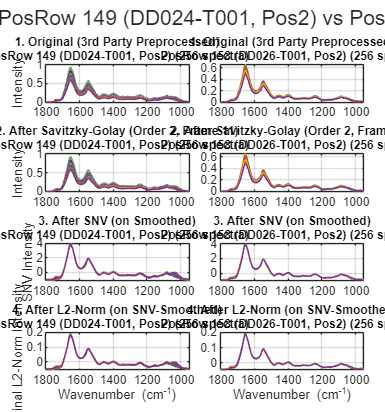

fig_filename_detail_tif_final = [figure_filename_base_detail_final, '.tif'];
print(fig_handle_detail_comp, fig_filename_detail_tif_final, '-dtiff', '-r300');

fprintf('Detailed comparison figure saved as: %s\n', fig_filename_detail_tif_final);

Detailed comparison figure saved as: comparison_all_spectra_pos149_vs_pos158_4stages.tif




fprintf('\n--- Full Workflow Script Complete ---\n');


--- Full Workflow Script Complete ---


disp('Final columns in data_all_positions include:');

Final columns in data_all_positions include:


disp(head(data_all_positions(:, find(ismember(data_all_positions.Properties.VariableNames, ...
    {'Proben_ID_str', 'Position', 'RawSpectrum', 'SmoothedSpectrum', 'SNV_on_Smoothed_Spectrum', 'FinalProcessedSpectrum'})))));

    Proben_ID_str    Position      RawSpectrum       SmoothedSpectrum    SNV_on_Smoothed_Spectrum    FinalProcessedSpectrum
    _____________    ________    ________________    ________________    ________________________    ______________________

    {'62376364'}     {'Pos1'}    {256×441 double}    {256×441 double}        {256×441 double}           {256×441 double}   
    {'62376364'}     {'Pos2'}    {256×441 double}    {256×441 double}        {256×441 double}           {256×441 double}   
    {'62376364'}     {'Pos3'}    {256×441 double}    {256×441 double}        {256×441 double}           {256×441 double}   
    {'62405084'}     {'Pos1'}    {256×441 double}    {256×441 double}        {256×441 double}           {256×441 double}   
    {'62405084'}     {'Pos2'}    {256×441 double}  